% This code creates tow datastores (training and validation), uploads
% Resnet50, makes desired adjustments, trains the network, classifies the
% datasets and determines confusion matrices, ROC curves and relevant
% metrics for both training and validation datasets.

% Based on Mathwork's example: https://es.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html

clear
clc


## Selection of databases for training and validation


imdsTrain = imageDatastore('C:\Users\pablosangil\Downloads\Datasets\Covid-19 RD Final\resnet\Train','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imageDatastore('C:\Users\pablosangil\Downloads\Datasets\Covid-19 RD Final\resnet\Validation','IncludeSubfolders',true,'LabelSource','foldernames');


## Uploading the Neural Network


net=resnet50;
net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input_1'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inputSize = net.Layers(1).InputSize;
if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 
[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1×2 Layer array with layers:

     1   'fc1000'                       Fully Connected         1000 fully connected layer
     2   'ClassificationLayer_fc1000'   Classification Output   crossentropyex with 'tench' and 999 other classes

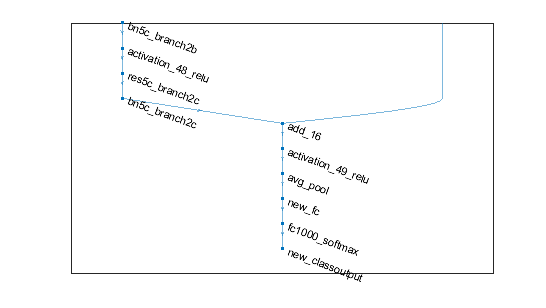

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);
figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

layers = lgraph.Layers;
connections = lgraph.Connections;

%layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);


## Data augmentation with spatial transformations


pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);


## Define training options


options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');


## Initialize training and classification


net = trainNetwork(augimdsTrain,lgraph,options);

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9421

idx = randperm(numel(imdsValidation.Files),4);

% Save net
save('my_resnet50','net')



## Confusion matrix and metrics for validation data

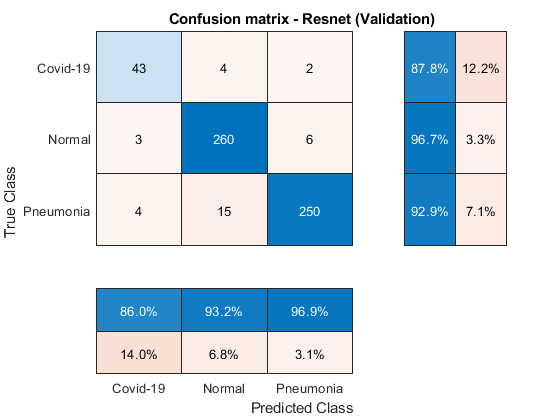

figure

cm=confusionchart(imdsValidation.Labels,YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
title('Confusion matrix - Resnet (Validation)');

metricas(cm)

ans = struct with fields:
        Accuracy: 94.2078
       Precision: [86 93.1900 96.8992]
    Sensibilidad: [87.7551 96.6543 92.9368]
       F_measure: [86.8687 94.8905 94.8767]
       G_measure: [86.8731 94.9063 94.8973]
    F_measureTot: 92.2388
    G_measureTot: 92.2390


## ROC Curve and AUC for validation data

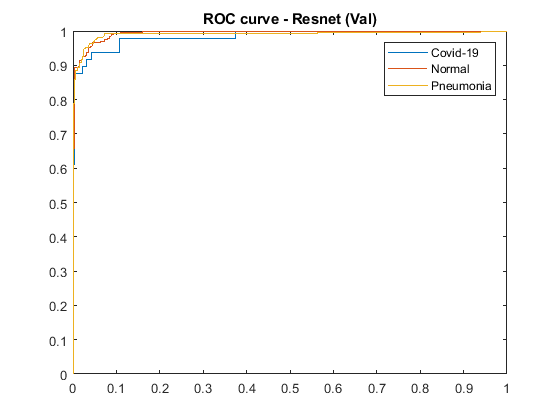

% ROC and AUC are determined for each class through one-vs-all
% classification

[Xco,Yco,Tco,AUCco] = perfcurve(imdsValidation.Labels,probs(:,1),'Covid-19');
[Xno,Yno,Tno,AUCno] = perfcurve(imdsValidation.Labels,probs(:,2),'Normal');
[Xpn,Ypn,Tpn,AUCpn] = perfcurve(imdsValidation.Labels,probs(:,3),'Pneumonia');

figure
plot(Xco,Yco)
hold on
plot(Xno,Yno)
plot(Xpn,Ypn)

hold off

legend('Covid-19','Normal','Pneumonia')
title('ROC curve - Resnet (Val)')


auc_text='AUC = %f\n';
fprintf(auc_text,AUCco,AUCno,AUCpn);

AUC = 0.984258
AUC = 0.994085
AUC = 0.990543


## Classification of the training data


[YPred,scores] = classify(net,augimdsTrain);
idx = randperm(numel(imdsTrain.Files),4);


## Confusion matrix and metrics of the training data

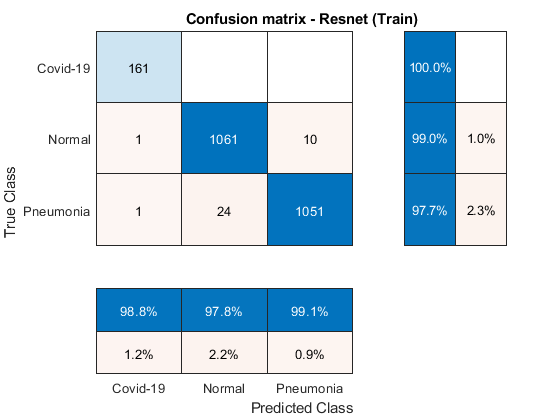

figure

cm=confusionchart(imdsTrain.Labels,YPred);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
title('Confusion matrix - Resnet (Train)');

metricas(cm)

ans = struct with fields:
        Accuracy: 98.4409
       Precision: [98.7730 97.7880 99.0575]
    Sensibilidad: [100 98.9739 97.6766]
       F_measure: [99.3827 98.3774 98.3622]
       G_measure: [99.3846 98.3792 98.3646]
    F_measureTot: 98.7112
    G_measureTot: 98.7113


## ROC curve and AUC of the training data

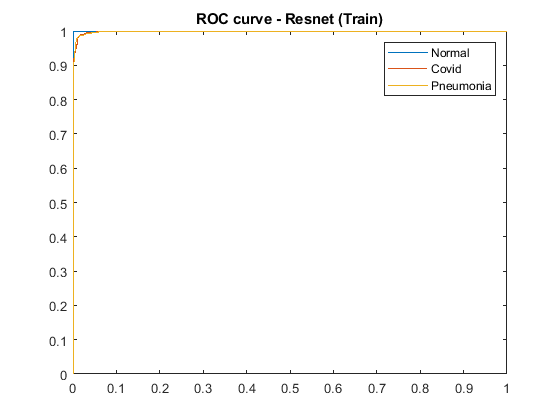


[Xco,Yco,Tco,AUCco] = perfcurve(imdsTrain.Labels,scores(:,1),'Covid-19');
[Xno,Yno,Tno,AUCno] = perfcurve(imdsTrain.Labels,scores(:,2),'Normal');
[Xpn,Ypn,Tpn,AUCpn] = perfcurve(imdsTrain.Labels,scores(:,3),'Pneumonia');

figure
plot(Xco,Yco)
hold on
plot(Xno,Yno)
plot(Xpn,Ypn)

hold off

legend('Normal','Covid','Pneumonia')
title('ROC curve - Resnet (Train)')


auc_text='AUC = %f\n';
fprintf(auc_text,AUCco,AUCno,AUCpn);

AUC = 1.000000
AUC = 0.998563
AUC = 0.998584
